# Tarea No. 3: Navegación por campo potencial

Eduardo Cuadros Montealegre

En este script de Matlab se ejecutan las etapas necesarias para la solución de una misión del robot con ruedas DR12 utilizando el método de navegación por campo potencial.

## Modelo cinemático del robot

### Dimensiones

X: 0.23 m    Y: 0.158 m    Z: 0.1406 m

Radio de rueda = 0.086 m    Espesor de rueda = 0.026 m

Distancia entre ruedas = 0.154 m

### Ecuaciones cinemáticas


$$v = \frac{r}{2} \dot{\theta_1} + \frac{r}{2} \dot{\theta_2}$$



$$w = \frac{r}{2l} \dot{\theta_1} - \frac{r}{2l} \dot{\theta_2} $$


radio_rueda = 0.086;
espesor_rueda = 0.026;
dist_ruedas = 0.23;
DR12 = differentialDriveKinematics(WheelRadius=radio_rueda, ...
    TrackWidth=dist_ruedas, VehicleInputs='VehicleSpeedHeadingRate')

DR12 =   differentialDriveKinematics with properties:

      VehicleInputs: 'VehicleSpeedHeadingRate'
         TrackWidth: 0.2300
        WheelRadius: 0.0860
    WheelSpeedRange: [-Inf Inf]


## Cálculo del radio R del circulo que circunscribe al robot

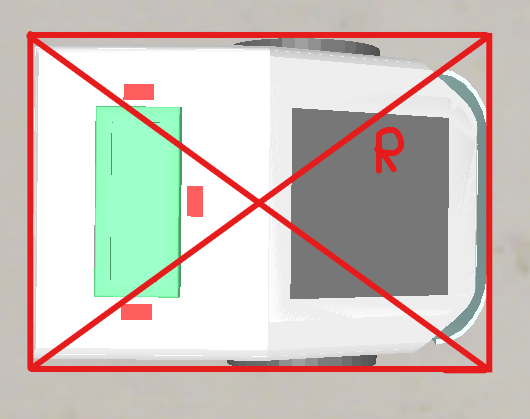


$$R =   \sqrt \left ( \left(\frac{0.158}{2} \right)^2 + \left(\frac{0.23}{2} \right)^2 \right) = 0.1395\ metros$$


## Arena

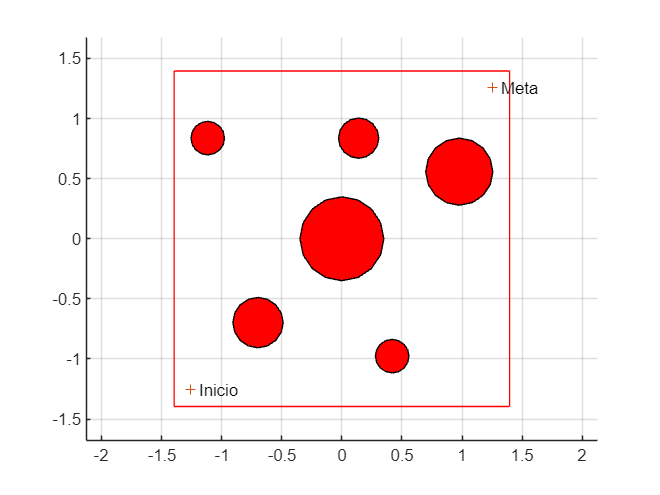

% ARENA2025 genera un área con obstáculos de perfil circular dadas las
% posiciones de los obstáculos en una matriz C y sus radios en un vector R
clf
figure(1)
hold on
k=10 * 0.1395;%factor de escala.
plot(k*[-1 1 1 -1 -1],k*[-1 -1 1 1 -1],'r')
CC=k*0.1*[3 -7;-5 -5;0 0;-8 6;1 6; 7 4];%centros de obstáculos
RC=k*0.1*[1 1.5 2.5 1 1.2 2];% radios de obstáculos.
t=0:pi/8:2*pi;
for i=1:length(RC)
patch(CC(i,1)+RC(i)*sin(t), CC(i,2)+RC(i)*cos(t),'r')
end
plot(k*[-.9,.9],k*[-.9,.9],'+')
text(-k*.85,-k*.9,'Inicio')
text(k*.95,k*.9,'Meta')
axis(k*[-1.2 1.2 -1.2 1.2])
axis equal
grid

Punto de inicio: (-1.1858, -1.2555)

Punto objetivo: (1.3253, 1.2555)

pos_init = [-1.1858, -1.2555];
pos_fin = [1.3253, 1.2555];

## Descripción del Campo Potencial Artificial


$$U_x = U_{att}(x) + U_{rep}(x)$$


El campo potencial atractivo se define como:


$$U_{att}(x)= \left\{ \begin{array}{lcc} \frac{1}{2}K_{att} ||x - x_{goal}||{^2} & si & ||x - x_{goal}|| \leq d\\ \\ dK_{att}||x - x_{goal}||{^2} - \frac{1}{2}K_{att}d{^2} & si & ||x - x_{goal}||> d  \end{array} \right.$$


Ya que la fuerza atractiva se define como el gradiente del campo potencial, definimos la fuerza potencial atractiva como:


$$\nabla U_{att}(x)= \left\{ \begin{array}{lcc} K_{att} ||x - x_{goal}|| & si & ||x - x_{goal}|| \leq d\\ \\ \frac{dK_{att}(x - x_{goal})}{ ||x - x_{goal}||}  & si & ||x - x_{goal}||> d  \end{array} \right.$$


Ahora definimos el campo potencial repulsivo generado por los obstáculos como:


$$U_{rep}(x)= \left\{ \begin{array}{lcc} \frac{1}{2}K_{rep} \left( \frac{1}{\rho(x)} - \frac{1}{\rho_0} \right)^2   & si &\rho(x)\leq \rho_0\\ \\0 & si & \rho(x) > \rho_0  \end{array} \right.$$


Por consiguiente, la fuerza de repulsión se define como:


$$U_{rep}(x)= \left\{ \begin{array}{lcc} -K_{rep} \left( \frac{1}{\rho(x)} - \frac{1}{\rho_0} \right) \frac{\nabla \rho(x)}{\rho(x)^2}   & si &\rho(x)\leq \rho_0\\ \\0 & si & \rho(x) > \rho_0  \end{array} \right.$$


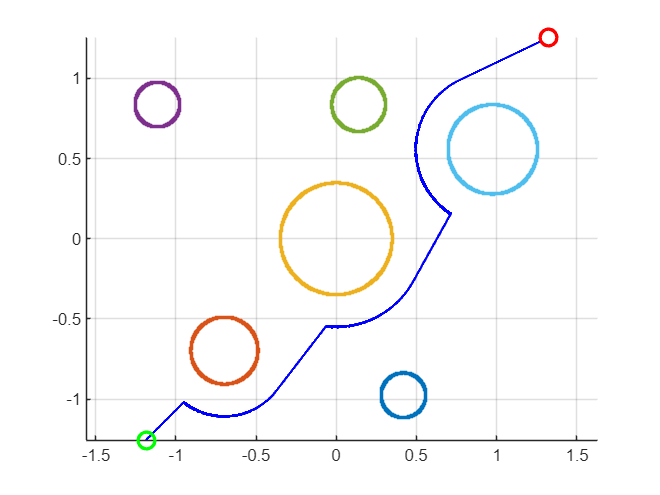

figure;hold on; axis equal; grid on;

obstacle_points = cell(length(RC), 1);

for i = 1:length(RC)
    obstacle_points{i} = generate_obs(CC(i,:), RC(i), 500);
    plot(obstacle_points{i}(:,1), obstacle_points{i}(:,2), '.', 'DisplayName', sprintf('Círculo %d', i));
end

Katt = 3.00;
Krep = 1;
rho_0 = 0.2;
d = 0.05;
step_size = 0.01;
threshold = 0.05;
max_iter = 5000;
x = pos_init;
path = pos_init;
x_goal = pos_fin;

for iter = 1:max_iter
    F_att = attractive_force(path(end,:), x_goal,d, Katt);
    F_rep = repulsive_force(path(end,:), obstacle_points, rho_0, Krep);
    F_total = F_att + F_rep;
    x = x - step_size * F_total;
    path = [path; x];
    if norm(x - x_goal) <= threshold
        break;
    end
end

hold on; axis equal; grid on;
plot(path(:,1), path(:,2), 'b-', 'LineWidth', 1.5);
plot(x_goal(1), x_goal(2), 'ro', 'MarkerSize', 10, 'LineWidth',2);
plot(path(1,1), path(1,2), 'go', 'MarkerSize',10, 'LineWidth', 2);

controller = controllerPurePursuit;
release(controller);
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.2;
controller.MaxAngularVelocity = 1.0;
controller.LookaheadDistance = 0.5;

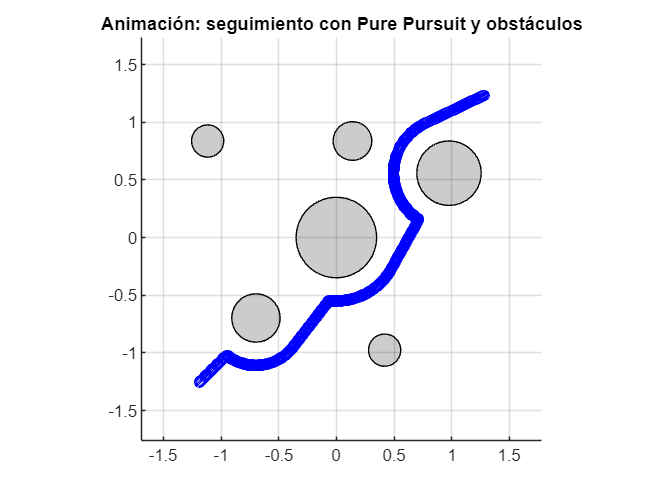

robotInitialLocation = path(1,:);
robotGoal = path(end,:);

initialOrientation = deg2rad(90); % orientación inicial real
robotCurrentPose = [robotInitialLocation, initialOrientation]';
goalRadius = 0.05;
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);
robot.TrackWidth = 0.3; % ancho entre ruedas (visualización)
frameSize = robot.TrackWidth / 0.8;

% --- Inicializar figura ---
figure;
axis equal; grid on;
xlim([min(path(:,1))-0.5, max(path(:,1))+0.5]);
ylim([min(path(:,2))-0.5, max(path(:,2))+0.5]);
title('Animación: seguimiento con Pure Pursuit y obstáculos');
hold on;

% --- Dibujar obstáculos circulares ---
theta_circ = linspace(0, 2*pi, 100);
for i = 1:length(RC)
    xc = CC(i,1) + RC(i)*cos(theta_circ);
    yc = CC(i,2) + RC(i)*sin(theta_circ);
    fill(xc, yc, 'k', 'FaceAlpha', 0.2);
end

% --- Dibujar trayectoria deseada ---
plot(path(:,1), path(:,2), 'b--o', 'DisplayName', 'Trayectoria APF');

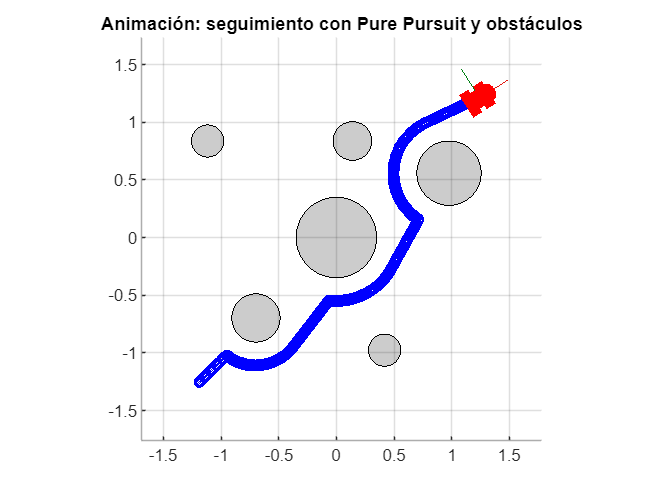


% --- Bucle de animación ---
distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
poses = robotCurrentPose';

while distanceToGoal > goalRadius
    % Velocidades del controlador
    [v, omega] = controller(robotCurrentPose);
    
    % Cinemática unicycle
    vel = [v * cos(robotCurrentPose(3));
           v * sin(robotCurrentPose(3));
           omega];
    
    % Actualizar pose
    robotCurrentPose = robotCurrentPose + vel * sampleTime;
    poses = [poses; robotCurrentPose'];
    
    % Dibujar escena
    cla;
    
    % Obstáculos
    for i = 1:length(RC)
        xc = CC(i,1) + RC(i)*cos(theta_circ);
        yc = CC(i,2) + RC(i)*sin(theta_circ);
        fill(xc, yc, 'k', 'FaceAlpha', 0.2);
    end

    % Trayectoria
    plot(path(:,1), path(:,2), 'b--o');

    % Dibujar robot con orientación
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    
    % Si tienes el STL del robot
    try
        plotTransforms(plotTrVec', plotRot, ...
            MeshFilePath="groundvehicle.stl", ...
            Parent=gca, View="2D", FrameSize=0.3);
    catch
        % Si no tienes el STL, usa flecha
        quiver(robotCurrentPose(1), robotCurrentPose(2), ...
               cos(robotCurrentPose(3))*0.2, sin(robotCurrentPose(3))*0.2, ...
               'r', 'LineWidth', 2);
    end
    
    % Actualizar distancia
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    waitfor(vizRate);
end

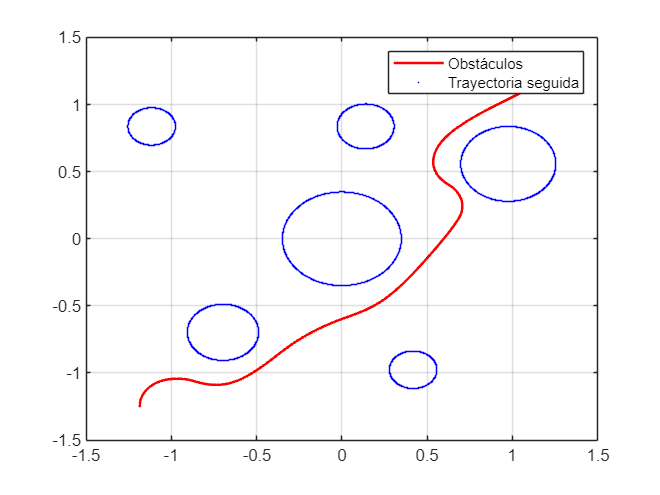

path_v4 = poses;
% Mostrar trayectoria recorrida
figure;
plot(poses(:,1), poses(:,2), 'r-', 'LineWidth', 1.5);
hold on; grid on;
for i = 1:length(RC)
    plot(obstacle_points{i}(:,1), obstacle_points{i}(:,2), '.', 'Color','b', 'MarkerSize', 1);
end
legend('Obstáculos', 'Trayectoria seguida');

[x_grid, y_grid] = meshgrid(-1.5:0.1:1.5, -1.5:0.1:1.5);
[rows, cols] = size(x_grid);
Fx = zeros(rows, cols);
Fy = zeros(rows, cols);
rad_goal = threshold * 2;
for i = 1:rows
    for j = 1:cols
        pos = [x_grid(i,j), y_grid(i,j)];
        in_obs = false;
        in_goal = false;
        for k = 1:length(RC)
            dist = norm(pos - CC(k,:));
            if dist < RC(k)
                in_obs = true;
                break;
            end
        end

        if norm(pos - x_goal) < (threshold * 2)
            in_obs = true;
        end

        if in_obs
            continue;
        end
       
        F_att = attractive_force(pos, x_goal, d, Katt);
        F_rep = repulsive_force(pos, obstacle_points, rho_0, Krep);
        F_total = F_att + F_rep;

        if norm(F_total) > 1e-4
            F_unit = - F_total / norm(F_total);
            Fx(i,j) = F_unit(1);
            Fy(i,j) = F_unit(2);
        end
    end
end


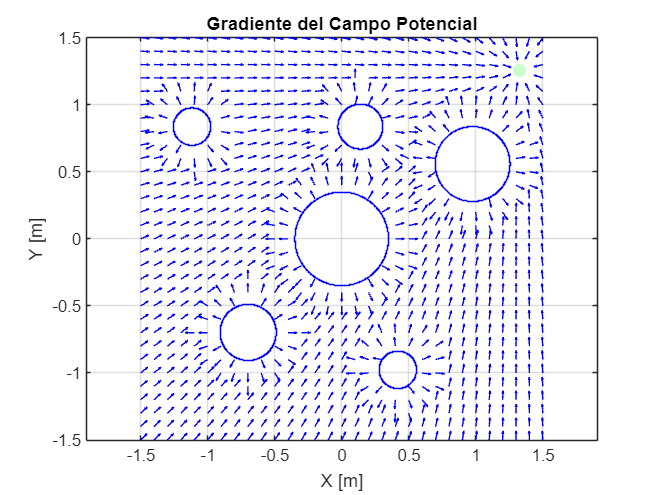

figure;
quiver(x_grid, y_grid, Fx, Fy, 0.5, 'b');
axis equal; grid on; hold on;
for i = 1:length(RC)
    plot(obstacle_points{i}(:,1), obstacle_points{i}(:,2), '.', 'Color','b', 'MarkerSize', 1);
end
theta_goal = linspace(0, 2*pi, 100);
xg = x_goal(1) + threshold * cos(theta_goal);
yg = x_goal(2) + threshold * sin(theta_goal);
fill(xg, yg, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('X [m]');
ylabel('Y [m]');
title('Gradiente del Campo Potencial')

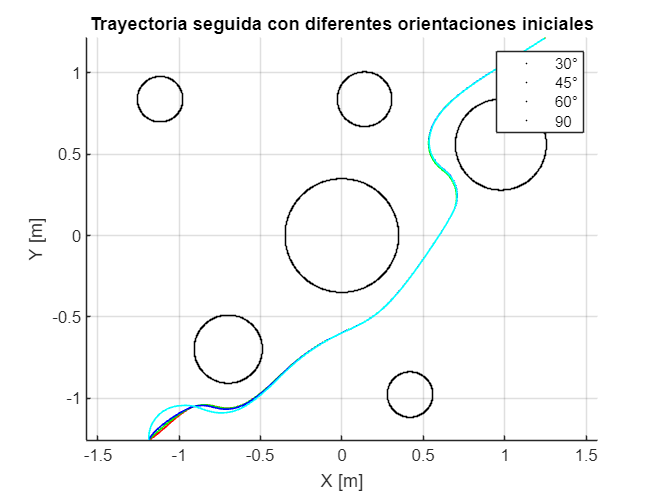

figure; grid on; axis equal; hold on
for i = 1:length(RC)
    plot(obstacle_points{i}(:,1), obstacle_points{i}(:,2), '.', 'Color','k', 'MarkerSize', 1);
end
plot (path_v1(:,1), path_v1(:, 2), 'r-', 'LineWidth', 1);
plot(path_v2(:,1), path_v2(:, 2), 'g-', 'LineWidth', 1);
plot(path_v3(:,1), path_v3(:, 2), 'b-', 'LineWidth', 1);
plot(path_v4(:,1), path_v4(:, 2), 'c-', 'LineWidth', 1);
legend('30°', '45°', '60°', '90')
title("Trayectoria seguida con diferentes orientaciones iniciales")
xlabel('X [m]');
ylabel('Y [m]');